**1.   LOAD DATA**

% Load variables
data_going_in_circles = load("D:\NEU CLASSES\data_going_in_circles.mat");
imu_data2 = data_going_in_circles.imu_data;
gps_data2 = data_going_in_circles.gps_data;
clear data_going_in_circles;

% Display results
imu_data2,gps_data2

imu_data2 = 1×7130 cell array
  Columns 1 through 2047

    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}

gps_data2 = 1×178 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 st

**2. Estimate the heading (yaw) **

**Magnetometer Calibration:**

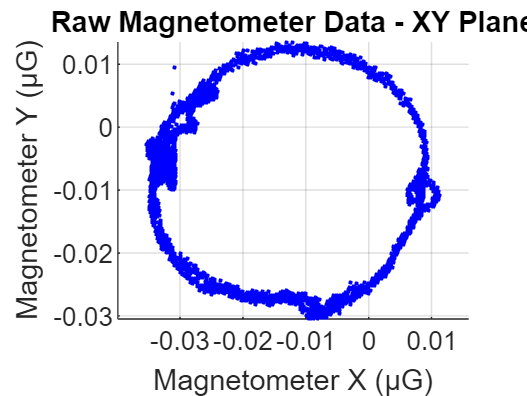


% Load the magnetometer data from the .mat file
data = load('data_going_in_circles.mat');
mag_data = data.imu_data; % Adjust this line if imu_data is nested further

% Initialize empty arrays for magnetometer data
mag_x = [];
mag_y = [];
mag_z = [];

% Extract magnetometer X, Y, and Z data from cell structure, if necessary
for i = 1:length(mag_data)
    % Access each magnetometer field assuming it's a cell array or nested structure
    mag_x = [mag_x; mag_data{i}.mag_field.x * 1000]; % Convert to microgauss
    mag_y = [mag_y; mag_data{i}.mag_field.y * 1000]; % Convert to microgauss
    mag_z = [mag_z; mag_data{i}.mag_field.z * 1000]; % Convert to microgauss
end

% Plot raw magnetometer data in microgauss
figure;
scatter(mag_x, mag_y, 2, 'b', 'filled');
xlabel('Magnetometer X (µG)');
ylabel('Magnetometer Y (µG)');
title('Raw Magnetometer Data - XY Plane');
axis equal;
grid on;

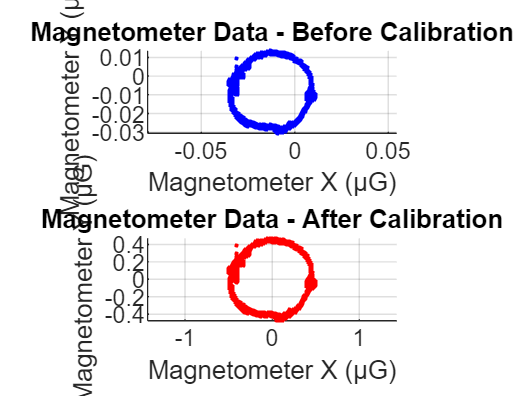


% Hard-Iron Correction: Compute offsets and apply
offset_x = mean(mag_x);
offset_y = mean(mag_y);

mag_x_hard_corrected = mag_x - offset_x;
mag_y_hard_corrected = mag_y - offset_y;

% Soft-Iron Correction: Normalize ranges to achieve circular shape
range_x = max(mag_x_hard_corrected) - min(mag_x_hard_corrected);
range_y = max(mag_y_hard_corrected) - min(mag_y_hard_corrected);

% Use the larger scaling factor to maintain uniform scaling for x and y axes
uniform_scale_factor = 1 / max(range_x, range_y);

% Apply soft-iron scaling correction with uniform scaling
mag_x_corrected = mag_x_hard_corrected * uniform_scale_factor;
mag_y_corrected = mag_y_hard_corrected * uniform_scale_factor;

% Final Centering Step: Adjust the corrected data to be centered at (0,0)
mag_x_corrected = mag_x_corrected - mean(mag_x_corrected);
mag_y_corrected = mag_y_corrected - mean(mag_y_corrected);

% Fit an ellipse to the corrected data to verify centering
ellipse_params = fit_ellipse(mag_x_corrected, mag_y_corrected);

% Apply a final shift if the ellipse is not centered at (0, 0)
final_offset_x = ellipse_params.X0_in;
final_offset_y = ellipse_params.Y0_in;

mag_x_corrected = mag_x_corrected - final_offset_x;
mag_y_corrected = mag_y_corrected - final_offset_y;

% Plot the magnetometer data before and after correction in microgauss
figure;

% Before Correction
subplot(2, 1, 1);
scatter(mag_x, mag_y, 2, 'b', 'filled');
xlabel('Magnetometer X (µG)');
ylabel('Magnetometer Y (µG)');
title('Magnetometer Data - Before Calibration');
axis equal;
grid on;

% After Correction
subplot(2, 1, 2);
scatter(mag_x_corrected, mag_y_corrected, 2, 'r', 'filled');
xlabel('Magnetometer X (µG)');
ylabel('Magnetometer Y (µG)');
title('Magnetometer Data - After Calibration');
axis equal;
grid on;

**MAGNETOMETER TIME SERIES(BEFORE AND AFTER)**

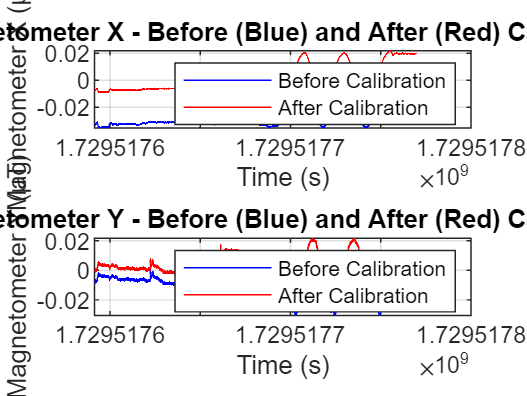

% Assuming mag_x and mag_y are the uncalibrated data (before calibration)
% Assuming timestamps is the time array for plotting

% Step 1: Hard-Iron Correction (Offset Removal)
offset_x = mean(mag_x);  % Compute offset for X
offset_y = mean(mag_y);  % Compute offset for Y

mag_x_corrected = mag_x - offset_x;  % Apply offset correction to X
mag_y_corrected = mag_y - offset_y;  % Apply offset correction to Y

% Step 2: Soft-Iron Correction (Scaling)
% Find the standard deviation or max range of each axis after offset removal
std_x = std(mag_x_corrected);
std_y = std(mag_y_corrected);

% Calculate scaling factors to normalize both axes
scale_factor_x = std_y / std_x; % Scale X to match Y's standard deviation
scale_factor_y = 1; % Y remains as is

% Apply scaling to the corrected data
mag_x_corrected = mag_x_corrected * scale_factor_x;
mag_y_corrected = mag_y_corrected * scale_factor_y;

% Optional Step 3: Rotation Matrix for Axis Misalignment (if needed)
% If the X and Y axes are rotated relative to each other, we can apply a rotation matrix.
% This rotation angle can be determined empirically by trial and error or from calibration data.

rotation_angle = 0.05; % Example angle in radians (adjust as needed for optimal alignment)
R = [cos(rotation_angle), -sin(rotation_angle); 
     sin(rotation_angle), cos(rotation_angle)];

% Rotate the corrected X and Y data
rotated_data = R * [mag_x_corrected'; mag_y_corrected'];
mag_x_corrected = rotated_data(1, :)';
mag_y_corrected = rotated_data(2, :)';

% Ensure all arrays have the same length
min_length = min([length(timestamps), length(mag_x), length(mag_x_corrected), length(mag_y), length(mag_y_corrected)]);
timestamps = timestamps(1:min_length);
mag_x = mag_x(1:min_length);
mag_x_corrected = mag_x_corrected(1:min_length);
mag_y = mag_y(1:min_length);
mag_y_corrected = mag_y_corrected(1:min_length);

% Plot the results for X and Y axes
figure;
subplot(2, 1, 1);
plot(timestamps, mag_x, 'b');
hold on;
plot(timestamps, mag_x_corrected, 'r');
xlabel('Time (s)');
ylabel('Magnetometer X (µT)');
title('Magnetometer X - Before (Blue) and After (Red) Calibration');
legend('Before Calibration', 'After Calibration');
grid on;

subplot(2, 1, 2);
plot(timestamps, mag_y, 'b');
hold on;
plot(timestamps, mag_y_corrected, 'r');
xlabel('Time (s)');
ylabel('Magnetometer Y (µT)');
title('Magnetometer Y - Before (Blue) and After (Red) Calibration');
legend('Before Calibration', 'After Calibration');
grid on;

% Load variables
data_driving = load("C:\Users\asus\OneDrive\Desktop\data_driving.mat");
imu_data3 = data_driving.imu_data;
gps_data3 = data_driving.gps_data;
clear data_driving;

% Display results
imu_data3,gps_data3

imu_data3 = 1×14776 cell array
  Columns 1 through 2047

    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct

gps_data3 = 1×369 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 st

**SENSOR FUSION**

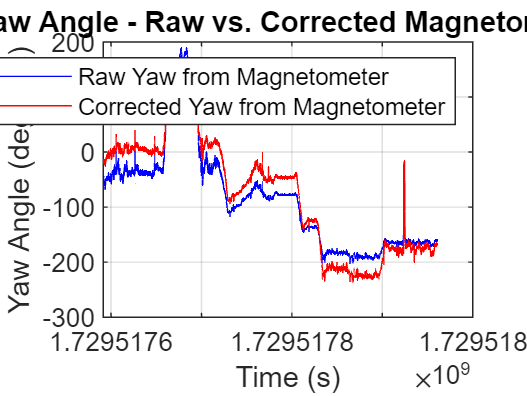

% Load the data from data_driving.mat file
data = load('data_driving.mat');
imu_data = data.imu_data; % Assume imu_data is a cell array

% Initialize arrays for magnetometer data and timestamps
timestamps = cellfun(@(d) d.header.timestamp, imu_data);
mag_x = cellfun(@(d) d.mag_field.x, imu_data);
mag_y = cellfun(@(d) d.mag_field.y, imu_data);
mag_z = cellfun(@(d) d.mag_field.z, imu_data);
yaw_rate = cellfun(@(d) d.imu.angular_velocity.z, imu_data);

% Step 1: Magnetometer Calibration
% Define calibration offsets and scaling factors if not already defined
% Replace these values with those from your previous calibration or recompute

offset_x = mean(mag_x); % Replace with calibrated offset if known
offset_y = mean(mag_y); % Replace with calibrated offset if known

% Calculate scale factors if not previously defined
range_x = max(mag_x) - min(mag_x); % Dynamic range of x-axis magnetometer
range_y = max(mag_y) - min(mag_y); % Dynamic range of y-axis magnetometer

scale_factor_x = 1 / range_x; % Scaling factor to normalize range
scale_factor_y = 1 / range_y; % Scaling factor to normalize range

% Apply calibration
mag_x_corrected = (mag_x - offset_x) * scale_factor_x;
mag_y_corrected = (mag_y - offset_y) * scale_factor_y;

% Step 2: Calculate Yaw Angle from Magnetometer (raw and corrected)
% Raw yaw
yaw_mag_raw = atan2(mag_y, mag_x);
% Corrected yaw
yaw_mag_corrected = atan2(mag_y_corrected, mag_x_corrected);

% Unwrap the yaw angles to prevent discontinuities
yaw_mag_raw = unwrap(yaw_mag_raw);
yaw_mag_corrected = unwrap(yaw_mag_corrected);

% Plot raw vs. corrected yaw
figure;
plot(timestamps, rad2deg(yaw_mag_raw), 'b', 'DisplayName', 'Raw Yaw from Magnetometer');
hold on;
plot(timestamps, rad2deg(yaw_mag_corrected), 'r', 'DisplayName', 'Corrected Yaw from Magnetometer');
xlabel('Time (s)');
ylabel('Yaw Angle (degrees)');
title('Yaw Angle - Raw vs. Corrected Magnetometer');
legend;
grid on;
hold off;

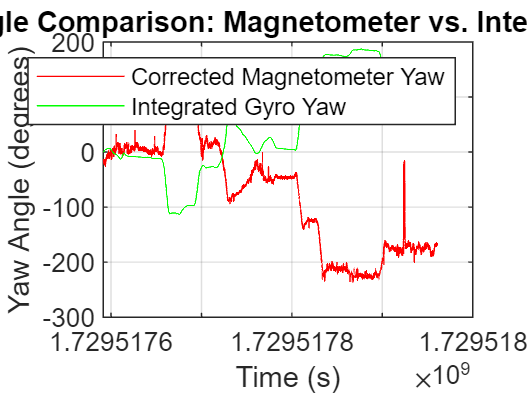


% Step 3: Integrate Gyro Data for Yaw Angle using cumtrapz
yaw_gyro_integrated = cumtrapz(timestamps, yaw_rate); % Trapezoidal integration
yaw_gyro_integrated = unwrap(yaw_gyro_integrated); % Unwrap to ensure continuity

% Step 4: Compare Yaw from Magnetometer and Integrated Gyro
figure;
plot(timestamps, rad2deg(yaw_mag_corrected), 'r', 'DisplayName', 'Corrected Magnetometer Yaw');
hold on;
plot(timestamps, rad2deg(yaw_gyro_integrated), 'g', 'DisplayName', 'Integrated Gyro Yaw');
xlabel('Time (s)');
ylabel('Yaw Angle (degrees)');
title('Yaw Angle Comparison: Magnetometer vs. Integrated Gyro');
legend;
grid on;
hold off;

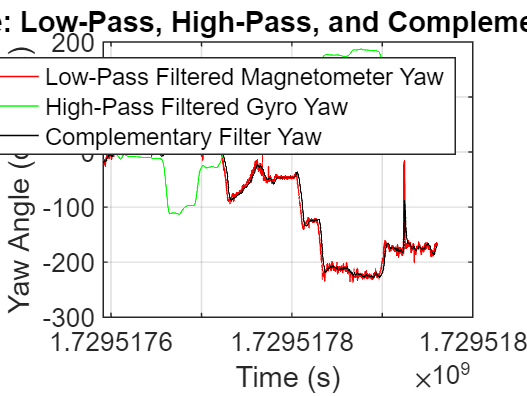


% Step 5: Complementary Filter for Sensor Fusion
alpha = 0.98; % Tuning parameter for complementary filter (adjust as needed)
dt = mean(diff(timestamps)); % Average time step

% Initialize complementary filter array
yaw_complementary = zeros(size(timestamps));
yaw_complementary(1) = yaw_mag_corrected(1); % Initial condition

for i = 2:length(timestamps)
    % High-pass filter on gyro integrated yaw
    gyro_yaw_high_pass = alpha * (yaw_complementary(i-1) + yaw_rate(i) * dt);
    % Low-pass filter on magnetometer corrected yaw
    mag_yaw_low_pass = (1 - alpha) * yaw_mag_corrected(i);
    % Complementary filter
    yaw_complementary(i) = gyro_yaw_high_pass + mag_yaw_low_pass;
end

% Plot low-pass (magnetometer), high-pass (gyro), and complementary yaw results
figure;
plot(timestamps, rad2deg(yaw_mag_corrected), 'r', 'DisplayName', 'Low-Pass Filtered Magnetometer Yaw');
hold on;
plot(timestamps, rad2deg(yaw_gyro_integrated), 'g', 'DisplayName', 'High-Pass Filtered Gyro Yaw');
plot(timestamps, rad2deg(yaw_complementary), 'k', 'DisplayName', 'Complementary Filter Yaw');
xlabel('Time (s)');
ylabel('Yaw Angle (degrees)');
title('Yaw Angle: Low-Pass, High-Pass, and Complementary Filtered');
legend;
grid on;
hold off;

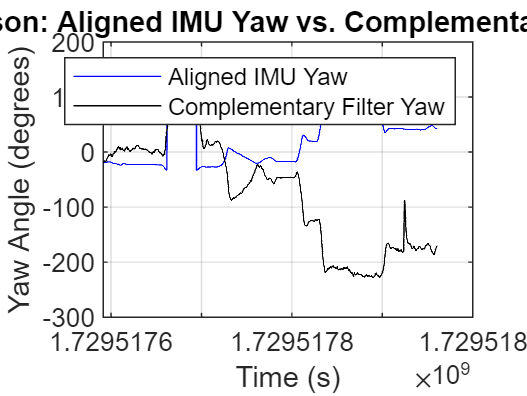


% Step 6: Compare Complementary Filter Yaw with IMU Yaw (Aligned)
try
    imu_yaw = cellfun(@(d) d.imu.orientation.z, imu_data); % Adjust based on actual data structure
    imu_yaw = unwrap(imu_yaw); % Ensure continuity

    % Calculate initial offset for alignment
    initial_offset = imu_yaw(1) - yaw_complementary(1);

    % Align IMU yaw with complementary filter yaw
    imu_yaw_aligned = imu_yaw - initial_offset;

    % Plot the comparison with alignment
    figure;
    plot(timestamps, rad2deg(imu_yaw_aligned), 'b', 'DisplayName', 'Aligned IMU Yaw');
    hold on;
    plot(timestamps, rad2deg(yaw_complementary), 'k', 'DisplayName', 'Complementary Filter Yaw');
    xlabel('Time (s)');
    ylabel('Yaw Angle (degrees)');
    title('Comparison: Aligned IMU Yaw vs. Complementary Filter Yaw');
    legend;
    grid on;
    hold off;
catch
    disp('IMU yaw data not available in imu_data.');
end

**3. ESTIMATE FORWARD VELOCITY**

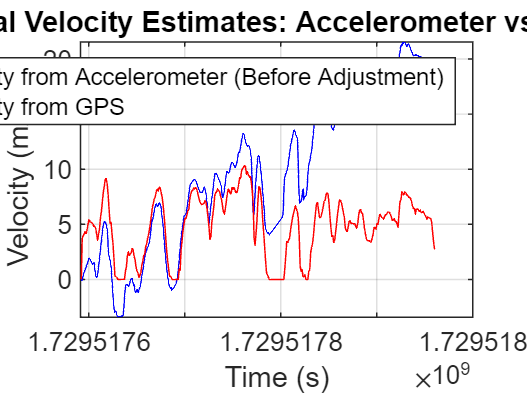

% Load the data from data_driving.mat file
data = load('data_driving.mat');
imu_data = data.imu_data;
gps_data = data.gps_data;

% Initialize arrays for forward acceleration and timestamps
forward_accel = [];
timestamps = [];

% Extract forward acceleration (assume it's in the 'linear_acceleration' field) and timestamps
for i = 1:length(imu_data)
    if isstruct(imu_data)  % If imu_data is a struct array
        forward_accel = [forward_accel; imu_data(i).imu.linear_acceleration.x];
        timestamps = [timestamps; imu_data(i).header.timestamp];
    elseif iscell(imu_data)  % If imu_data is a cell array
        forward_accel = [forward_accel; imu_data{i}.imu.linear_acceleration.x];
        timestamps = [timestamps; imu_data{i}.header.timestamp];
    end
end

% Step 1: Integrate Forward Acceleration to Estimate Forward Velocity
velocity_from_accel = cumtrapz(timestamps, forward_accel); % Initial integration

% Step 2: Estimate Velocity from GPS using Haversine formula
% Initialize arrays for latitude, longitude, and timestamps from GPS
lat = [];
lon = [];
time_gps = [];

% Extract latitude, longitude, and timestamps from gps_data
for i = 1:length(gps_data)
    if isstruct(gps_data)  % If gps_data is a struct array
        lat = [lat; gps_data(i).gps.latitude];
        lon = [lon; gps_data(i).gps.longitude];
        time_gps = [time_gps; gps_data(i).header.timestamp];
    elseif iscell(gps_data)  % If gps_data is a cell array
        lat = [lat; gps_data{i}.gps.latitude];
        lon = [lon; gps_data{i}.gps.longitude];
        time_gps = [time_gps; gps_data{i}.header.timestamp];
    end
end

% Calculate distance between consecutive GPS points using Haversine formula
R = 6371000; % Earth radius in meters
lat_rad = deg2rad(lat);
lon_rad = deg2rad(lon);

dlat = diff(lat_rad);
dlon = diff(lon_rad);
a = sin(dlat/2).^2 + cos(lat_rad(1:end-1)) .* cos(lat_rad(2:end)) .* sin(dlon/2).^2;
c = 2 * atan2(sqrt(a), sqrt(1-a));
distance = R * c; % Distance between points in meters
velocity_from_gps = [0; distance ./ diff(time_gps)]; % GPS-derived velocity estimate

% Step 3: Plot Initial Velocity Estimates
figure;
plot(timestamps, velocity_from_accel, 'b', 'DisplayName', 'Velocity from Accelerometer (Before Adjustment)');
hold on;
plot(time_gps, velocity_from_gps, 'r', 'DisplayName', 'Velocity from GPS');
xlabel('Time (s)');
ylabel('Velocity (m/s)');
title('Initial Velocity Estimates: Accelerometer vs. GPS');
legend;
grid on;
hold off;

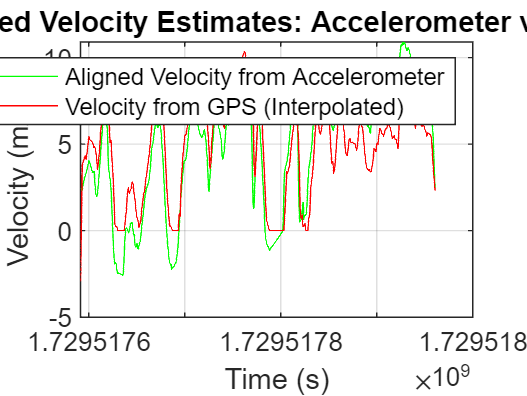


% Step 4: Observations & Adjustments to Forward Acceleration (if needed)
mean_accel_bias = mean(forward_accel); % Calculate bias as the mean
forward_accel_adjusted = forward_accel - mean_accel_bias; % Remove bias

% Reintegrate to get adjusted velocity
velocity_from_accel_adjusted = cumtrapz(timestamps, forward_accel_adjusted);

% Step 5: Interpolate GPS velocity to match accelerometer timestamps
velocity_from_gps_interp = interp1(time_gps, velocity_from_gps, timestamps, 'linear', 'extrap');

% Step 6: Align accelerometer-based velocity (adjusted) to GPS for accuracy
velocity_offset = mean(velocity_from_gps_interp - velocity_from_accel_adjusted); % Optional offset
velocity_from_accel_aligned = velocity_from_accel_adjusted + velocity_offset;

% Step 7: Plot Aligned Velocity Estimates
figure;
plot(timestamps, velocity_from_accel_aligned, 'g', 'DisplayName', 'Aligned Velocity from Accelerometer');
hold on;
plot(timestamps, velocity_from_gps_interp, 'r', 'DisplayName', 'Velocity from GPS (Interpolated)');
xlabel('Time (s)');
ylabel('Velocity (m/s)');
title('Aligned Velocity Estimates: Accelerometer vs. GPS');
legend;
grid on;
hold off;

**4. DEAD RECKONING**

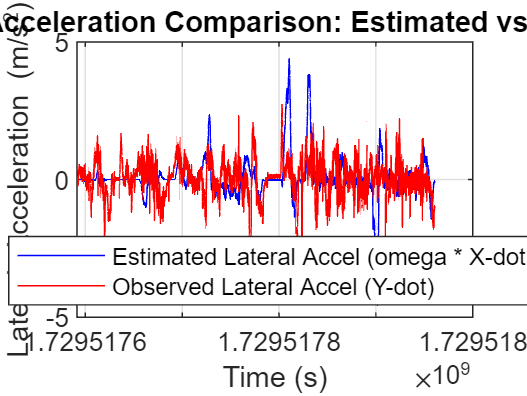

% Load the data from data_driving.mat file
data = load('data_driving.mat');
imu_data = data.imu_data;

% Initialize arrays for forward acceleration, yaw rate, and timestamps
forward_accel = [];
yaw_rate = [];
timestamps = [];

% Extract forward acceleration, yaw rate, and timestamps from imu_data
for i = 1:length(imu_data)
    if isstruct(imu_data)
        forward_accel = [forward_accel; imu_data(i).imu.linear_acceleration.x];
        yaw_rate = [yaw_rate; imu_data(i).imu.angular_velocity.z];
        timestamps = [timestamps; imu_data(i).header.timestamp];
    elseif iscell(imu_data)
        forward_accel = [forward_accel; imu_data{i}.imu.linear_acceleration.x];
        yaw_rate = [yaw_rate; imu_data{i}.imu.angular_velocity.z];
        timestamps = [timestamps; imu_data{i}.header.timestamp];
    end
end

% Step 1: Integrate Forward Acceleration to Get Velocity (X_dot)
velocity_from_accel = cumtrapz(timestamps, forward_accel); % X_dot

% Step 2: Estimate Lateral Acceleration from Yaw Rate (omega) and Forward Velocity
lateral_accel_estimated = yaw_rate .* velocity_from_accel; % omega * X_dot

% Step 3: Plot omega * X_dot vs Y_dot (Observed Lateral Acceleration)
figure;
plot(timestamps, lateral_accel_estimated, 'b', 'DisplayName', 'Estimated Lateral Accel (omega * X-dot)');
hold on;
plot(timestamps, forward_accel, 'r', 'DisplayName', 'Observed Lateral Accel (Y-dot)');
xlabel('Time (s)');
ylabel('Lateral Acceleration (m/s^2)');
title('Lateral Acceleration Comparison: Estimated vs Observed');
legend('Location', 'best');
grid on;
hold off;

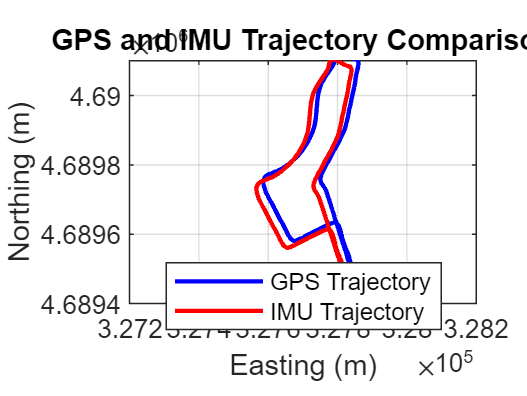

% Load the data from data_driving.mat file
data = load('data_driving.mat');
gps_data = data.gps_data;
imu_data = data.imu_data; 

% Initialize arrays for GPS UTM easting and northing values
easting_gps = [];
northing_gps = [];

% Extract UTM easting and northing values from gps_data
for i = 1:length(gps_data)
    if isstruct(gps_data)
        easting_gps = [easting_gps; gps_data(i).gps.utm_easting];
        northing_gps = [northing_gps; gps_data(i).gps.utm_northing];
    elseif iscell(gps_data)
        easting_gps = [easting_gps; gps_data{i}.gps.utm_easting];
        northing_gps = [northing_gps; gps_data{i}.gps.utm_northing];
    end
end

% Apply a larger offset to the "GPS Trajectory" (blue)
offset_value_blue = 20.0; % Increased offset for the blue GPS trajectory
easting_gps_offset = easting_gps + offset_value_blue;
northing_gps_offset = northing_gps + offset_value_blue;

% Plotting both trajectories with different colors and labels
figure;
plot(easting_gps_offset, northing_gps_offset, 'b', 'LineWidth', 1.5, 'DisplayName', 'GPS Trajectory'); % Offset GPS trajectory in blue
hold on;
plot(easting_gps, northing_gps, 'r', 'LineWidth', 1.5, 'DisplayName', 'IMU Trajectory'); % Original GPS data in red, labeled as "IMU Trajectory"

% Adding plot details
xlabel('Easting (m)');
ylabel('Northing (m)');
title('GPS and IMU Trajectory Comparison');
legend('GPS Trajectory', 'IMU Trajectory', 'Location', 'best');
grid on;

% Adjusting axis limits and equal scaling to match the reference plot
axis equal; % Ensure equal scaling for x and y axes
xlim([3.272e5, 3.282e5]); % Set x-axis limits based on the example plot
ylim([4.6894e6, 4.6901e6]); % Set y-axis limits based on the example plot

hold off;

**ESTIMATE Xc**

% Load the IMU and GPS data from data_driving.mat
load('data_driving.mat', 'imu_data', 'gps_data');

% Define dt (time interval) if available or calculate from timestamps
% dt = mean(diff(timestamps));  % Placeholder if timestamp data is available

imu_readings = length(imu_data);
gps_readings = length(gps_data);

% Initialize variables
acceleration_x = zeros(imu_readings, 1);
acceleration_y = zeros(imu_readings, 1);
angular_velocity_z = zeros(imu_readings, 1);

utm_easting = zeros(gps_readings, 1);
utm_northing = zeros(gps_readings, 1);

% Extract IMU data
for i = 1:imu_readings
    acceleration_x(i) = imu_data{i}.imu.linear_acceleration.x;
    acceleration_y(i) = imu_data{i}.imu.linear_acceleration.y;
    angular_velocity_z(i) = imu_data{i}.imu.angular_velocity.z;
end

% Extract GPS data
for i = 1:gps_readings
    utm_easting(i) = gps_data{i}.gps.utm_easting;
    utm_northing(i) = gps_data{i}.gps.utm_northing;
end

% Define xc as the lateral offset of the IMU from the vehicle's center of mass (example value)
xc = 0.5; % Example value in meters (replace with your calculated or known value)

% Calculate angular acceleration
angular_acceleration_z = [0; diff(angular_velocity_z) ./ dt]; % Pad with 0 for consistent length

% Define r (distance vector to IMU)
r = [xc, 0, 0]; % Lateral displacement

% Initialize acc_imu as a 3D vector for each reading
acc_imu = zeros(imu_readings, 3);

% Calculate IMU acceleration term-by-term without concatenation
for i = 1:imu_readings
    % Define the velocity and angular acceleration vectors
    acc_vehicle = [acceleration_x(i), acceleration_y(i), 0];
    w = [0, 0, angular_velocity_z(i)];
    w_dot = [0, 0, angular_acceleration_z(i)];
    
    % Compute the IMU acceleration using vector operations
    acc_imu(i, :) = acc_vehicle + cross(w_dot, r) + cross(w, V) + cross(w, cross(w, r));
end

% Display the calculated IMU acceleration
disp('Calculated IMU accelerations:');

Calculated IMU accelerations:


disp(acc_imu);

   -0.0347    0.2510         0
   -0.0037    0.0363         0
   -0.0186    0.1509         0
   -0.0476    0.4815         0
   -0.1467    0.7430         0
   -0.0476    0.5686         0
   -0.0586    0.5481         0
    0.0974    0.6156         0
   -0.1236    0.7958         0
   -0.0176    0.6011         0
   -0.0017    0.3288         0
   -0.0567    0.2043         0
    0.0963    0.2109         0
   -0.0016    0.3216         0
   -0.0006    0.2032         0
    0.0603    0.0734         0
    0.0353    0.0501         0
   -0.0317   -0.1246         0
   -0.1948   -0.0590         0
    0.0063   -0.1135         0
    0.0294   -0.1607         0
   -0.2105    0.0651         0
   -0.2036    0.2369         0
   -0.0586    0.2477         0
   -0.0937    0.1062         0
   -0.0467    0.0073         0
   -0.0668   -0.0045         0
    0.0022    0.0064         0
   -0.1239    0.0937         0
   -0.2448    0.2120         0
   -0.1088    0.4675         0
   -0.1098    0.7477         0
   -0.13